# Matrix Representations of Linear Systems

 This live script is intended to be used with the code hidden. Select the `VIEW` tab and switch to `Hide Code`.

## Why use matrices?

Matrix representations have several useful qualities. Four are illustrated here.

- Matrices offer a compact representation for linear systems of equations

- Matrices are useful for representing solution algorithms to linear systems of equations

- The solvability of a linear system can be ascertained through matrix properties

- Decompositions of matrices can offer meaningful insight into the dynamics of large systems

 1. Systems with many similar parts can often benefit from a matrix representation. For example, a lumped parameter model of a blood vessel network can be represented in matrix form:

$\mathbf{C}\frac{d\mathbf{p}}{dt} = \mathbf{R}\mathbf{p}$.

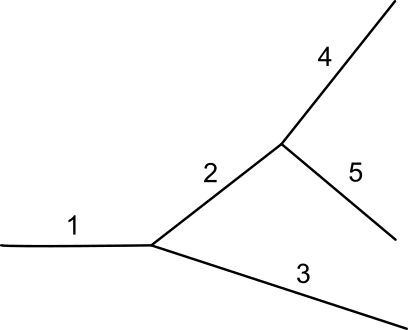

*A small vessel network*

2. Consider a linear transformation that rotates a coordinate system:

*[illustratation of a coordinate system rotation, the unused system is grayed out in both pictures, arrows between pictures are labeled with the matrix required to transform between the systems]*

The transformation from the first coordinate system to the second can be represented as

    
$$\hat\mathbf{x} = \mathbf{A} \mathbf{x}$$


If you want to reverse the transformation, you can use the matrix inverse ($\mathbf{A}^{-1}$):

    $\mathbf{x} = \mathbf{A}^{-1} \hat\mathbf{x}$.

3. A system of $n$ linear equations with $n$ variables can have a unique solution, infinite solutions, or no solutions. 

*[images of systems with unique, infinite, and no solutions]*

If you write the system in matrix form, $\mathbf{A} \mathbf{x} = \mathbf{b}$, the properties of the coefficient matrix $\mathbf{A}$ supply information on the solvability of the system.

4. Decomposing the coefficient matrix of a system, especially a system of ODEs, can offer insight into the physical dynamics of that system.

*[Illustration of multiple connected masses]*

This system of connected masses will vibrate in natural modes. The equations of motion can be written in matrix form $\ddot\mathbf{x} = \mathbf{Ax}$. By computing the eigenvalue decomposition of $\mathbf{A = V \Lambda V^{-1}}$, you can identify the oscillation frequencies (the eigenvalues, $\lambda$) and the shape of the modes (the eigenvectors, $\mathbf{v}$).

*[animated illustration of frequencies and modes of oscillation]*

## Systems of linear equations

**Definition**. A *system of linear equations* (also called a *linear system*) is a set of linear equations. A *linear equation* only contains terms that either multiples of variables (e.g. $1.2x$) or constants. That is, it can be expressed in the form:

     
$$a_1x_1 + a_2x_2 + a_3x_3 +  \ldots = b$$


where each $a_i$ and $b$ are constants and each $x_i$ is a variable.

- In this live script, only systems with equal numbers of variables and equations are examined. **Overdetermined** (more equations than unknowns) and **underdetermined **(fewer equations than unknowns) are not considered.

#### **Write a linear system in matrix form**

Consider the set of linear equations

    $\begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
ax + by + z = d
\end{array}$   (⁎)

where $a$ and $b$ are constants. You can write this system in matrix form, $\mathbf{Ax} = \mathbf{b}$, by defining a variable vector $\mathbf{x}$, a constant vector $\mathbf{b}$, and a coefficient matrix $\mathbf{A}$. 

Suppose that you have defined the variable vector

    
$$\mathbf{x} = \left( \matrix{x \cr y \cr z} \right)$$


what are the coefficient matrix $\mathbf{A}$ and constant vector $\mathbf{b}$?

showSolution = false;
[A,bvec] = linearEquationSltn(showSolution);

  **Try**

- Compute the matrix-vector product $\mathbf{Ax}$. Does the result match the LHS (left-hand side) of the linear system (⁎)?

#### **Visualize a linear system**

You can visualize 2- and 3-dimensional linear systems. For a 3-dimensional system, each equation appears as a plane. The plot below shows the linear system

   $\left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & -1\\
a & b & 1
\end{array}\right)
\left( \matrix{x \cr y \cr z} \right)
=
\left(\begin{array}{c}
2\\
-2\\
d
\end{array}\right)$   (⁎)

with values specified for $a$, $b$, and $d$.

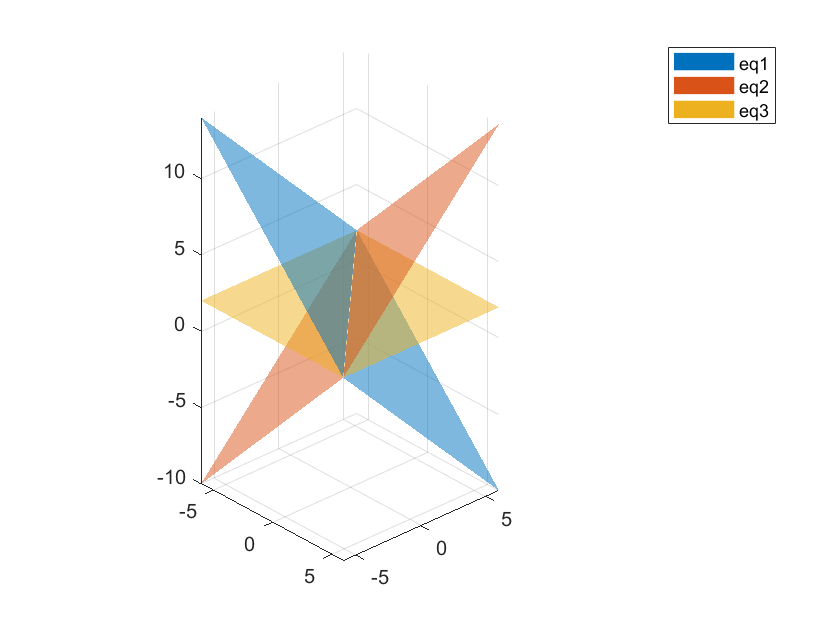

$$eq1 = x+y+z=2$$

$$eq2 = x+y-z=-2$$

$$eq3 = z=2$$

 
a = 0; % Default: 1
b = 0; % Default: -1
d = 2; % Default: -1
A = sym([1 1 1; 1 1 -1; a b 1]);
bvec = sym([2; -2; d]);
lims = [-6,6];
[eq1,eq2,eq3] = plot3DSystem(A,bvec,lims) % This function plots the planes

 **Reflect**

For each set of constants, how many solutions are there to the system?

- $a = -1$, $b = 1$, and $d = 2$

- $a = 0$, $b = 0$, and $d = 2$

- $a = 0$, $b = 0$, and $d = -4$

## Solving linear systems

#### **Solve a linear system using elimination**

In elementary algebra, you solve a linear system using substitution or elimination.

** Exercise**. Solve the linear system using the elimination method.

    $\begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
-x + y + z = 2
\end{array}$ (⁑)

showSolution = true;
A = [1 1 1; 1 1 -1; -1 1 1];
b = [2; -2; 2];
if(showSolution)
    syms x y z
    sltn = [x;y;z] == A\b
end

$$sltn = \left(\begin{array}{c} x=0\\ y=0\\ z=2 \end{array}\right)$$

#### **Solve a linear system in matrix form**

When solving a linear system in matrix form, you use the same fundamental operations used in elimination. Consider the matrix representation of (⁑):

    
$$\left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & -1\\
-1 & 1 & 1
\end{array}\right)
\left( \matrix{x \cr y \cr z} \right)
=
\left(\begin{array}{c}
2\\
-2\\
2
\end{array}\right)$$


In matrix form, a solution of this system appears as:

    $\left(\begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0 \\
0 & 0 & 1
\end{array}\right)
\left( \matrix{x \cr y \cr z} \right)
= \text{solution vector}$,

because, multiplying the LHS out yields:

    $\left( \matrix{x \cr y \cr z} \right)
= \text{solution vector}$.

To simplify the notation for obtaining this form of the system, the whole systems is typically written as:

   $\left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & -1\\
-1 & 1 & 1
\end{array}\right|
\left.\begin{array}{c}
2\\
-2\\
2
\end{array}\right)$.

In this form, each row represents an equation. It is not necessary to write the variable vector, as each column of the matrix already corresponds to a variable. To solve a system in this form, you can use the same operations you use in elimination:

- Multiply any row by a constant

- Add a row to another row (multiplying by a constant before adding, if needed)

- Swap any row with another row

These are often termed **elementary row operations**. 

** Example**. Solve the linear system (⁑) using elementary row operations. The corresponding algebraic notation is shown for reference and the bold typeface is used for emphasis.

                                                             Matrix representation           Algebraic notation

                                                               
$$\left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & -1\\
-1 & 1 & 1
\end{array}\right|
\left.\begin{array}{c}
2\\
-2\\
2
\end{array}\right)$$
            
$$\left\{\begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
-x + y + z = 2
\end{array}\right.$$


1. Add row 1 to **row 3** [→](https://en.wikipedia.org/wiki/%E2%86%92_(disambiguation))                         $\left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & -1\\
\mathbf 0& \mathbf 2 & \mathbf 2
\end{array}\right|
\left.\begin{array}{c}
2\\
-2\\
\mathbf 4
\end{array}\right)$              $\left\{ \begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
\mathbf{2y + 2z = 4}
\end{array}$

2. Add  -1×row 1 to **row 2 **[→](https://en.wikipedia.org/wiki/%E2%86%92_(disambiguation))                   $\left(\begin{array}{ccc}
1 & 1 & 1\\
0 & 0 & \mathbf{-2}\\
0 & 2 & 2
\end{array}\right|
\left.\begin{array}{c}
2\\
\mathbf{-4}\\
4
\end{array}\right)$              $\left\{ \begin{array}{r}
x + y + z = 2
\\ 
\mathbf{- 2z = -4}
\\
2y + 2z = 4
\end{array}$

3. Swap **row 2 and 3** [→](https://en.wikipedia.org/wiki/%E2%86%92_(disambiguation))                          $\left(\begin{array}{ccc}
1 & 1 & 1\\
0 & \mathbf 2 & \mathbf 2\\
0 & 0 & \mathbf {-2}
\end{array}\right|
\left.\begin{array}{c}
2\\
\mathbf{-4} \\
\mathbf {4}
\end{array}\right)$               $\left\{ \begin{array}{r}
x + y + z = 2
\\
\mathbf{2y + 2z = -4}
\\ 
\mathbf{- 2z = 4}
\end{array}$

4. Divide **rows 2 and 3** by 2 and -2 [→](https://en.wikipedia.org/wiki/%E2%86%92_(disambiguation))     $\left(\begin{array}{ccc}
1 & 1 & 1\\
0 & \mathbf  1 & \mathbf 1\\
0 & 0 & \mathbf{1}
\end{array}\right|
\left.\begin{array}{c}
2\\
\mathbf {-2}\\
\mathbf {-2}
\end{array}\right)$                 $\left\{ \begin{array}{r}
x + y + z = 2
\\
\mathbf{y + z = - 2}
\\ 
\mathbf{z = -2}
\end{array}$

5. Subtract row 2 from **row 1** [→](https://en.wikipedia.org/wiki/%E2%86%92_(disambiguation))               $\left(\begin{array}{ccc}
\mathbf{1} & \mathbf{0} & \mathbf{0}\\
0 & 1 & 1\\
0 & 0 & 1
\end{array}\right|
\left.\begin{array}{c}
\mathbf{0} \\
-2\\
-2
\end{array}\right)$                 $\left\{ \begin{array}{r}
\mathbf{x = 0}
\\
y + z = 4
\\ 
z = -2
\end{array}$

6. Subtract row 3 from **row 2** [→](https://en.wikipedia.org/wiki/%E2%86%92_(disambiguation))               $\left(\begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right|
\left.\begin{array}{c}
0 \\
0 \\
-2
\end{array}\right)$                 $\left\{ \begin{array}{r}
x = 0
\\
\mathbf{y  = 0}
\\ 
z = -2
\end{array}$

Implying the solution is $x = 0, \ y = 0, \ z = -2%$

  **Try**. Convert the solved matrix form (shown below) back into algebraic notation using matrix arithmetic.

                
$$\left(\begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right|
\left.\begin{array}{c}
0 \\
0 \\
-2
\end{array}\right)$$


**Definition**. The solution form (obtained in step 6) is known as **reduced row echelon form**, which is characterized by the following properties:

- The leading entry in each nonzero row is to the right of the leading entry of the preceding row.

- Each leading entry of a nonzero row is 1 and is called a **pivot**.

- Rows of all zeros are below nonzero rows.

- In any pivot column, every entry besides the pivot is zero.

- The pivot of a row must be to the right of the pivot in a preceding row.

Note that this form only applies to matrix (the LHS), not the RHS of the equation.

** Exercise**. Solve for the reduced row echelon form of the system:

    
$$\begin{array}{r}
x + y + z = \ \ 2
\\ 
x + y - z = -2
\\
 z = \ \ 2
\end{array}$$


showSolution = true;
if(showSolution)
    reduced_row_echelon_form = sym(rref([1 1 1 2; 1 1 -1 -2; 0 0 1 2]))
end

$$reduced\_row\_echelon\_form = \left(\begin{array}{cccc} 1 & 1 & 0 & 0\\ 0 & 0 & 1 & 2\\ 0 & 0 & 0 & 0 \end{array}\right)$$

 **Reflect**

- The solution to this system is the infinite set: $\{(x,y,z): z = 2 \text{ and } y=-x\}$. How is this reflected in the reduced row echelon form?

## Square matrix inverses

A *square matrix* has an equal number of rows and columns. Such matrices are suitable for representing systems with an equal numbers of equations and unknowns. The **inverse** of a $n \times n$ matrix $A$ (if it exists) is denoted $A^{-1}$, and satisfies:

    
$$A^{-1} A = I$$


where $I$ is the $n \times n$ identity matrix: 

    
$$I = \left(\begin{array}{cccc} 1 & 0 & 0 & \ldots \\ 0 & 1 & 0 &  \\ 0 & 0 & 1 &  \\ \vdots &  &  & \ddots \end{array}\right)$$


Note that not every square matrix has an inverse.

#### **Computing the matrix inverse by row reduction**

One way to think of the matrix inverse is that it encodes all of the operations required to convert $A$ into reduced row echelon form (which, for a matrix that has an inverse, is always the identity matrix). Following this line of thinking leads naturally to a method for computing the inverse of a matrix: by using row reduction. However, you need a matrix that stores those operations. Thus, when computing the matrix inverse of a 3x3 matrix $A$ with elements $a_{ij}$ by row reduction, you write it together with an identity matrix as 

    $\left(\begin{array}{ccc}
a_{11} & a_{12} & a_{13}\\
a_{21} & a_{22} & a_{23}\\
a_{31} & a_{32} & a_{33}\\
\end{array}\ \right| \ \left.\begin{array}{c}
1 & 0 & 0 \\
0 & 1 & 0 \\
0 & 0 & 1 
\end{array}\right)$.

Then, you use row operations to convert $A$ into the identity matrix. The operations are encoded in the right side matrix, producing $A^{-1}$.

** Example**. Solve for the inverse of $A$ using using row operations.

    
$$A = 
\left(\begin{array}{ccc}
0.5 &  2 & 1\\
1 & 2 & -1\\
-1 & 0 & -4
\end{array}\right)
$$


if(~exist("kstep","var"))
    AI = [];
    kstep = 0;
end
[AI,kstep] = invDialogue(AI,kstep);

$$\mathrm{6. Divide rows 2 and 3 by -2 and -8}$$

$$\left(\begin{array}{cccccc} 1 & 4 & 2 & 2 & 0 & 0\\ 0 & -2 & -3 & -2 & 1 & 0\\ 0 & 0 & -8 & -2 & 2 & 1 \end{array}\right)\to \left(\begin{array}{cccccc} 1 & 4 & 2 & 2 & 0 & 0\\ 0 & 1 & \frac{3}{2} & 1 & \frac{-1}{2} & 0\\ 0 & 0 & 1 & \frac{1}{4} & \frac{-1}{4} & \frac{-1}{8} \end{array}\right)$$

** Exercise**. Verify that $A^{-1}$ computed in the example above is the inverse of $A$ (verify that $A^{-1}A$ equals $I$).

            $A = 
\left(\begin{array}{ccc}
0.5 &  2 & 1\\
1 & 2 & -1\\
-1 & 0 & -4
\end{array}\right)
$,    $\mathrm{A^{-1} =\ }\mathrm{}\left(\begin{array}{ccc}
-1 & 1 & -\frac{1}{2}\\
\frac{5}{8} & -\frac{1}{8} & \frac{3}{16}\\
\frac{1}{4} & -\frac{1}{4} & -\frac{1}{8}
\end{array}\right)$

#### **Formulas for inverses of 2x2 and 3x3 matrices**

The inverse of a 2x2 matrix 

        $A = \left(\begin{array}{cc}
a & b\\
c & d
\end{array}\right)$  is  $A^{-1} = \frac{1}{ad - bc} \left(\begin{array}{cc}
d & -b\\
-c &a
\end{array}\right)$.

The inverse of a 3x3 matrix 

        $A =
\left(\begin{array}{ccc}
a & b & c\\
d & e & f\\
g & h & i
\end{array}\right)$   is   $A^{-1} =
\frac{1}{a\,e\,i-a\,f\,h-b\,d\,i+b\,f\,g+c\,d\,h-c\,e\,g}
\left(\begin{array}{ccc}
e\,i-f\,h & -b\,i+c\,h& b\,f-c\,e\\
-d\,i+f\,g& a\,i-c\,g & -a\,f+c\,d\\
d\,h-e\,g & -a\,h+b\,g & a\,e-b\,d
\end{array}\right)$.

For larger matrices, the formulas become quite complicated.

show4x4 = true;
if(show4x4)
    A = sym("a",[4,4])
    inv(A)
end

$$A = \left(\begin{array}{cccc} a_{1,1} & a_{1,2} & a_{1,3} & a_{1,4}\\ a_{2,1} & a_{2,2} & a_{2,3} & a_{2,4}\\ a_{3,1} & a_{3,2} & a_{3,3} & a_{3,4}\\ a_{4,1} & a_{4,2} & a_{4,3} & a_{4,4} \end{array}\right)$$

show5x5 = true;
if(show4x4)
    A = sym("a",[5,5])
    inv(A)
end

$$A = \left(\begin{array}{ccccc} a_{1,1} & a_{1,2} & a_{1,3} & a_{1,4} & a_{1,5}\\ a_{2,1} & a_{2,2} & a_{2,3} & a_{2,4} & a_{2,5}\\ a_{3,1} & a_{3,2} & a_{3,3} & a_{3,4} & a_{3,5}\\ a_{4,1} & a_{4,2} & a_{4,3} & a_{4,4} & a_{4,5}\\ a_{5,1} & a_{5,2} & a_{5,3} & a_{5,4} & a_{5,5} \end{array}\right)$$

  **Try **

- Use row-reduction techniques to compute the general inverse of the 2x2 matrix $A$.

- Verify the formula for the 2x2 matrix inverse by computing $A^{-1} A$.

 **Reflect**

- For many square matrices, the inverse does not exist, despite the existence of the general formula. Review the formulas for the inverses of the 2x2 and 3x3 matrices shown above. What condition would lead to an undefined inverse?

#### **Invertibility of square matrices**

**Definition**. A $n\times n$ matrix is said to be **invertible** if its inverse exists.

**Conditions for invertibility**

A square $n\times n$ matrix is invertible if and only if:

- its determinant is nonzero.

The invertibility of a sqaure matrix can be linked to many properties that are outside the scope of the concepts discussed here.

- the rank of the matrix is $n$

function [A,bvec] = linearEquationSltn(showSolution)
    A = [];
    bvec = [];
    if(showSolution)
        syms a b d
        A = sym([1 1 1; 1 1 -1; a b 1]) 
        bvec = sym([2; -2; d])
    end
end

function [eq1,eq2,eq3] = plot3DSystem(A,bvec,lims)
    % Solve for z
    syms x y z;
    xvec = [x; y; z];
    eqs = A*xvec == bvec;
    eq1 = eqs(1);
    eq2 = eqs(2);
    eq3 = eqs(3);
    f1 = solve(eq1,z);
    f2 = solve(eq2,z);
    f3 = solve(eq3,z);
    % Create the plot
    c = lines(5);
    fsurf(f1,lims,"facecolor",c(1,:),"facealpha",0.5,"edgecolor","none")
    hold on;
    fsurf(f2,lims,"facecolor",c(2,:),"facealpha",0.5,"edgecolor","none")
    fsurf(f3,lims,"facecolor",c(3,:),"facealpha",0.5,"edgecolor","none")
    hold off
    axis equal;
    view (10,30); 
    axis tight
    legend("eq1","eq2","eq3")
end

function [AI,k] = invDialogue(AI,k)
    AIprev = AI;
    switch k
        case 1
            text = "1. Write A and I together as a single matrix";    
            AI = sym([0.5 2 1 1 0 0; 1 2 -1 0 1 0; -1 0 -4 0 0 1]);
        case 2
            text = "2. Add row 2 to row 3";
            AI(3,:) = AI(3,:) + AI(2,:);
        case 3
            text ="3. Add -2*row 1 to row 2";
            AI(2,:) = AI(2,:) + -2*AI(1,:);
        case 4
            text ="4. Multiply row 1 by 2";
            AI(1,:) = 2*AI(1,:) ;
        case 5
            text ="5. Add row 2 to row 3";
            AI(3,:) = AI(3,:) + AI(2,:);
        case 6
            text = "6. Divide rows 2 and 3 by -2 and -8";
            AI(2,:) = AI(2,:)/-2;
            AI(3,:) = AI(3,:)/-8;
        case 7
            text = "7. Subtract -1.5*row 3 from row 2";
            AI(2,:) = AI(2,:) - 1.5*AI(3,:);
        case 8
            text = "8. Subtract -4*row 2 and -2*row 3 from row 1";
            AI(1,:) = AI(1,:) - 4*AI(2,:) - 2*AI(3,:);
        case 9
            text = "The matrix inverse is contained in the last three columns.";
        otherwise
            AI = sym([0.5 2 1; 1 2 -1; -1 0 -4]);
            k = 0;
            text = "0. The matrix A:";
    end
    
    AI = combine(AI);
    displayFormula("'" + text + " '")
    if(k == 9)
        displayFormula(["'A⁻¹ = '", char(AI(:,4:6))]);
    elseif (k == 0)
        displayFormula(["'A = '", char(AI)]);
    else      
        displayFormula([char(AIprev) , "'→'" , char(AI)])
    end
    k = k+1;
end

% Suppress unusued suggestions
%#ok<*IJCL> 
%#ok<*NOPRT>